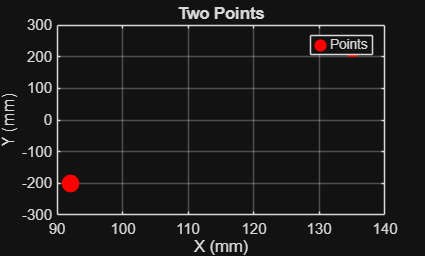

x = [92, 135];
y = [-201, 226];

figure;
plot(x, y, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
grid on;
xlabel('X (mm)');
ylabel('Y (mm)');
title('Two Points');
legend('Points');

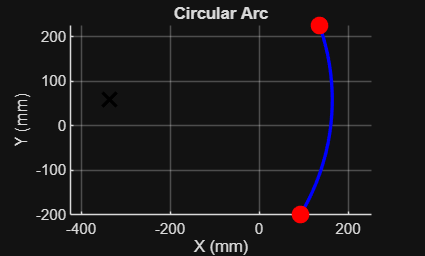

P1 = [92, -201];
P2 = [135, 226];

R = 500; % choose your radius in mm

% Midpoint and perpendicular bisector
M = (P1 + P2) / 2;
d = P2 - P1;
chord = norm(d);

% Distance from midpoint to center
h = sqrt(R^2 - (chord/2)^2);

% Unit perpendicular
perp = [-d(2), d(1)] / chord;

% Two possible centers (pick one side)
C1 = M + h * perp;
C2 = M - h * perp;
C = C1; % change to C2 to flip the arc

% Angles from center to each point
theta1 = atan2(P1(2)-C(2), P1(1)-C(1));
theta2 = atan2(P2(2)-C(2), P2(1)-C(1));

% Arc angles
theta = linspace(theta1, theta2, 300);
x_arc = C(1) + R * cos(theta);
y_arc = C(2) + R * sin(theta);

% Plot
figure; hold on;
plot(x_arc, y_arc, 'b-', 'LineWidth', 2);
plot([P1(1), P2(1)], [P1(2), P2(2)], 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(C(1), C(2), 'kx', 'MarkerSize', 12, 'LineWidth', 2);
grid on; axis equal;
xlabel('X (mm)'); ylabel('Y (mm)');
title('Circular Arc');